# ME 140 In Class Ch 6 Open Methods - 10.2.25

## Problem 6.3

Determine the highest real root of f(x) = x^3-6*x^2+11*x-6.1.

a. Graphically

b. Newton-Raphson method (Newton's Method), 3 iterations, x0 = 3.5

c. Secant method (3 iter, x-1 = 2.5, x0 = 3.5

d. Modified secant (3 iter, x0 = 3.5, delta = 0.01

e. Find all roots with Matlab

#### Graphically

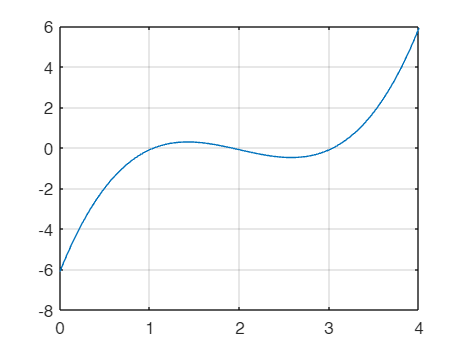

x = linspace(0,4);
y = x.^3-6*x.^2+11.*x-6.1;
plot(x,y)
grid

#### Newton-Raphson

% see notebook
f = @(x) x^3-6*x^2+11*x-6.1;
fp = @(x) 3*x^2-12*x+11; % have to find deriv directly
x_old = 3.5;

% make this a loop breh
for i = 1:3
    x_new = x_old-f(x_old)/fp(x_old)
    ea = abs(x_new-x_old)/x_new
    x_old = x_new;
end;

x_new = 3.1913

ea = 0.0967

x_new = 3.0687

ea = 0.0400

x_new = 3.0473

ea = 0.0070

#### Secant Method

x_old = 3.5; x_v_old = 2.5;
for i = 1:3
    x_new = x_old-f(x_old)*(x_v_old - x_old)/(f(x_v_old)-f(x_old))
    ea = abs(x_new-x_old)/x_new
    x_v_old = x_old;
    x_old = x_new; 
end

x_new = 2.7111

ea = 0.2910

x_new = 2.8711

ea = 0.0557

x_new = 3.2219

ea = 0.1089

% big error at beginning

#### Modified Secant

x_old = 3.5; delta = 0.01;
for i = 1:3
    x_new = x_old-delta*(f(x_old))/(f(x_old+delta)-f(x_old))
    ea = abs(x_new-x_old)/x_new
    x_old = x_new;
end

x_new = 3.1937

ea = 0.0959

x_new = 3.0707

ea = 0.0401

x_new = 3.0477

ea = 0.0075

#### Matlab

% Built-in functions
r = roots([1 -6 11 -6.1]) % give coefficients

r =     3.0467
    1.8990
    1.0544


c = poly(r) % Get polynomial coefficients from roots

c =     1.0000   -6.0000   11.0000   -6.1000


fz_ig = fzero(f,3.5)

fz_ig = 3.0467

fz_ir = fzero(f,[2 4])

fz_ir = 3.0467


% Custom codes - it helps if you print out the help menu to start with
%help modSecant
%help newtraph
%help secant

% Newton-Raphson
func = f; dfunc = fp; xr = 3.5;
[root_NR,ea_NR,iter_NR]=newtraph(func,dfunc,xr) % Newton Raphson

root_NR = 3.0467

ea_NR = 1.8219e-05

iter_NR = 5

[root_nr,ea_nr,iter_nr]=newtraph_autodiff(func,xr) % No need deriv!!!!

root_nr = 3.0467

ea_nr = 1.8219e-05

iter_nr = 5


% Secant method
x1 = 2.8; x2 = 5; % Note: depending on x1 and x2, may hit issues
xr_S=secant(f,x1,x2) % secant method

xr_S = 3.0467


x = 3.5;
xr_MS=modSecant(f,x,delta) % mod secant

xr_MS = 3.0467

## In-Class 5

Employ the Newton-Raphson method to determine a real root for the polynomial below. Use an initial guess of 4.5. 

b) Determine all the roots of the polynomial with MATLAB ( i.e. use roots())

f(x) = -2+6*x-4*x^2+0.5*x^3

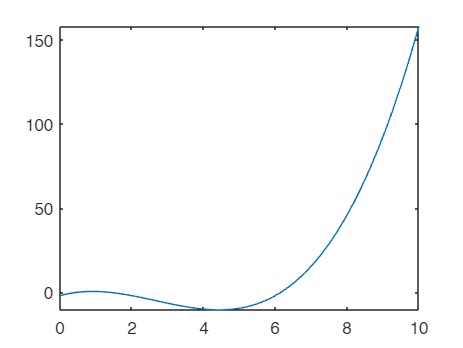

f = @(x) -2+6*x-4*x^2+0.5*x^3;
fplot(f,[0 10]);

help newtraph

  newtraph: Newton-Raphson root location zeroes
  [root,ea,iter]=newtraph(func,dfunc,xr,es,maxit,p1,p2,...):
  uses Newton-Raphson method to find the root of func
  input:
    func = name of function
    dfunc = name of derivative of function
    xr = initial guess
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    root = real root
    ea = approximate relative error (%)
    iter = number of iterations



func = f; xr = 4.5;
dfunc = @(x) 6-8*x+1.5*x^2;
[root_NR,ea_NR,iter_NR]=newtraph(func,dfunc,xr)

root_NR = 6.1563

ea_NR = 1.0026e-06

iter_NR = 11


% Custom Newton_Raphson method that internally 
% calculates the derivative
[root_NRc,ea_NRc,iter_NRc]=newtraph_autodiff(func,xr)

root_NRc = 6.1563

ea_NRc = 1.0026e-06

iter_NRc = 11


% Calculate all roots with MATLAB
r = roots([0.5 -4 6 -2])

r =     6.1563
    1.3691
    0.4746



% Note: there's a function I found that'll automatically
% extract coefficients
syms x;
coeff = sym2poly(f(x)); % Gets in vector form

coeff =     0.5000   -4.0000    6.0000   -2.0000


r_coeff = roots(coeff)

r_coeff =     6.1563
    1.3691
    0.4746
